localUsername = getenv('USERNAME');
listOfUsernames = {'aryan', 'Aryan Ritwajeet Jha'};
if ismember(localUsername,  listOfUsernames)
    % For user 'aryan', change the current directory to the specified path
    cd(strcat("C:", filesep, "Users", filesep, localUsername, filesep, "Documents", filesep, ...
        "documents_general", filesep, "MultiPeriod-DistOPF-Benchmark", filesep, "functions", filesep, ...
        "OneTimeScripts", filesep, "validationAgainstOpenDSS_MATLAB") )
    addpath(genpath('dss_matlab\'))
    addpath(genpath('../../'))
    latex_interpreter
else
    fprintf("Are you not me? Might want to add the folder to the path or add folder to the workspace.\n");
end

systemName = sysInfo.systemName;
kVA_B = sysInfo.kVA_B;
kV_B = sysInfo.kV_B;
CVR = [0 0];

DSSObj = DSS_MATLAB.IDSS;

DSSText=DSSObj.Text;
DSSCircuit=DSSObj.ActiveCircuit;
DSSBus = DSSCircuit.ActiveBus;
% Locating the master file for this system, with some starting 
% information to get the simulation running
MasterFileString = strcat('Compile (.\', systemName, 'master_r.dss)'); 
DSSText.Command = MasterFileString;
text_powerdata_r = 'powerdata.txt';
Power_data = readmatrix(text_powerdata_r);
varNames0 = {"busNum", "P_L", "Q_L", "Q_C", "P_D", "busType"};
varNames = cellfun(@char, varNames0, 'UniformOutput', false);
busData = readtable(text_powerdata_r);
busData.Properties.VariableNames = varNames;

N = length(busData.busNum);
busNums = busData.busNum;
P_L = busData.P_L;
Q_L = busData.Q_L;
Q_C = busData.Q_C;
% P_D = busData.P_D;
busTypes = busData.busType;

## Load dss generation

stLoadTitle = '! Specifying Loads as Model 1 and 2 type loads. For no CVR, Model 2 loads will be blank';
DSSTest.Command = stLoadTitle;
for i = 1:N
    if P_L(i) || Q_L(i)
        % Model=1 is constant power load, Model=2 is constant current load
        sta1 = strcat('New load.S', num2str(busNums(i)),'P    Bus=',num2str(busNums(i)),...
            '.1   Phases=1   Model=1   kv=2.4018   kw=',num2str(P_L(i)*(1-(CVR(1)/2))),...
            '  kvar=',num2str(Q_L(i)*(1-(CVR(2)/2))),'   Vminpu=0.95  Vmaxpu=1.05'  );
        
       DSSText.Command = sta1;

       if CVR ~= [0 0]
           sta2 = strcat('New load.S', num2str(busNums(i)),'Z    Bus=',num2str(busNums(i)),...
               '.1   Phases=1  Model=2   kv=2.4018   kw=',num2str(P_L(i)*((CVR(1))/2)),...
               '  kvar=',num2str(Q_L(i)*((CVR(2))/2)),'    Vminpu=0.95  Vmaxpu=1.05'  );
              DSSText.Command = sta2;
       end
    end
end

## PV Data

% qD= zeros(nBus,1);   % All the Q values in all the buses
% qD= Dec_Var*1000;   % DOPF
simName = vald.simInfo.simName;
V_copf = vald.V_copf;
qD_AreaFull_1toT = vald.qD_AreaFull_1toT;
pD_AreaFull_1toT = vald.pD_AreaFull_1toT;
qD = qD_AreaFull_1toT*kVA_B;
pD = pD_AreaFull_1toT*kVA_B;
% conn=wye
% PV_bus = [];%[68 98] ;
for i = 1:N
    if pD(i)
        % if isempty(find(PV_bus==i, 1))
            stGa = strcat('New generator.', num2str(busNums(i)),'  Phases=1   Bus1=',num2str(busNums(i)),...
                '.1   kV = 2.4018 Model=1  kW=', num2str(pD(i)),'  kVAr=', num2str(qD(i)));
            DSSText.Command = stGa;
            
        % else % generators for PV buses
        %     stGa = strcat('New generator.',num2str(busNums(i)),'  Phases=1   Bus1=',num2str(busNums(i)),...
        %         '.1   kV = 2.4018 Model=3 kW=',num2str(pD(i)),'  Minkvar = ',num2str(-3*abs(qD(i))));
        %     DSSText.Command = stGa;
        % end
        
    end
end

## Capacitors

smallkW = 0.000001;
% smallkW = 0
for i = 1:N
    if Q_C(i)
        stC = strcat('New generator.',num2str(busNums(i)),'C','  Phases=1   Bus1=',num2str(busNums(i)),...
            '   kV = 2.4018 Model=1 kW=',num2str(smallkW),'   kVAr=',num2str(Q_C(i)));
        % stC = strcat('New Capacitor.C',num2str(busNums(i)),'  Phases=1   Bus1=',num2str(busNums(i)),...
        %     '   kV = 2.4018 kVAr=',num2str(Q_C(i)));
        DSSText.Command = stC;
    end
end

## Line parameter

text_linedata_r = 'linedata.txt';
Line_data = readmatrix(text_linedata_r);

nBranch = size(Line_data,1);
for i = 1:nBranch
    stLn = strcat('New Line.L', num2str(i),'   Phases = 1  Bus1= ', num2str(Line_data(i,1)),'  bus2 = ',...
        num2str(Line_data(i,2)),'  r1=', num2str(Line_data(i,3)),...
        '  x1= ',num2str(Line_data(i,4)));
    DSSText.Command =stLn;
end

DSSText.Command = 'Set VoltageBases = [4.16]' ; %  ! ARRAY OF VOLTAGES IN KV
DSSText.Command = 'CalcVoltageBases' ; %! PERFORMS ZERO LOAD POWER FLOW TO ESTIMATE VOLTAGE BASES

DSSText.Command = 'Set maxcontroliter=200';
DSSText.Command = 'solve mode=snap';

DSSSolution     = DSSCircuit.Solution;

DSSObj.AllowForms = false;
% DSSText.Command = 'Totals'
% Totals = DSSCircuit.TotalPower;
% Loads = DSSCircuit.Loads
% DSSCircuit.TotalPower
% DSSCircuit.
DSSSolution.Solve;

Generators = DSSCircuit.Generators;

% Initialize variables to sum the generation values
genNumber = Generators.First();
genkWsum = 0.0;
genkvarsum = 0.0;

% Iterate through each generator
while genNumber > 0
    genkWsum = genkWsum + Generators.kW();
    genkvarsum = genkvarsum + Generators.kvar();
    genNumber = Generators.Next();
end

% Now genkWsum and genkvarsum hold the total kW and kVAr generation, respectively

Loads = DSSCircuit.Loads;
loadnumber = Loads.First();
loadkWsum = 0.0;
loadkvarsum = 0.0;

while loadnumber > 0
    loadkWsum = loadkWsum + Loads.kW();
    loadkvarsum = loadkvarsum + Loads.kvar();
    loadnumber = Loads.Next();
end

% loadkWsum, loadkvarsum

### Save .DSS file

% ext = ".dss";
% filename = char(strcat(systemName, "_", simName, ext))
% % filename = 'hello123.dss';
% saveCommand = ['Save Circuit "', filename, '"'];
% DSSText.Command = saveCommand;
% disp(strcat("DSS file exported to ", filename));
% V_PU = [];
V_PU = DSSCircuit.AllBusVmagPU;
MytotalCircuitLosses= (DSSCircuit.Losses)/1000;

DSSCircuit.SetActiveElement('Line.L1');
MyPowerArray = DSSCircuit.ActiveCktElement.Powers;
P_Sub = sum(MyPowerArray(1));
Q_Sub = sum(MyPowerArray(2));
Line_loss = MytotalCircuitLosses;
V_opds = zeros(N,1);
BUS_phase = DSSCircuit.AllNodeNames;
for i = 1:length(BUS_phase)
    X = BUS_phase{i};
    X_len = length(X);
    col = str2double(X(end));
    row = str2double(X(1:(X_len-2)));
    V_opds(row,col) = V_PU(i);
end
V_opds = V_opds';

disp('------------------------------------------------------------')

------------------------------------------------------------



disp(['Line Loss: ', num2str(Line_loss(1)),' kW'])

Line Loss: 12.0904 kW


% else
disp(['Substation Power: ', num2str(P_Sub),' kW + ', num2str(Q_Sub),' kVAr'])

Substation Power: 768.167 kW + 149.0344 kVAr


disp(['Total Load: ', num2str(loadkWsum), ' kW + ', num2str(loadkvarsum), ' kVAr'])

Total Load: 1163.197 kW + 640.012 kVAr


disp(['Total Generation: ', num2str(genkWsum), ' kW + ', num2str(genkvarsum), ' kVAr' ])

Total Generation: 407.1205 kW + 514.2525 kVAr


% disp(['Total Real Load: ', num2str(loadkWsum), ' kW'])
% disp(['Total Reactive Load: ', num2str(loadkvarsum), ' kVAr'])
disp(['Total PV Real Power Generation: ', num2str(genkWsum), ' kW'])

Total PV Real Power Generation: 407.1205 kW


disp(['Total Reactive Power Generation: ', num2str(genkvarsum), ' kVAr'])

Total Reactive Power Generation: 514.2525 kVAr


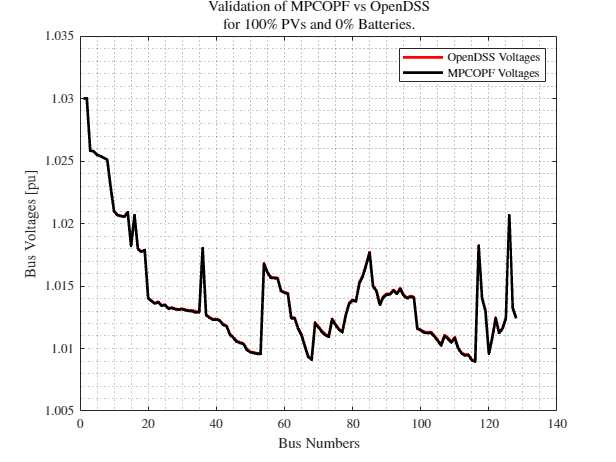

DER_percent = vald.simInfo.DER_percent;
Batt_percent = vald.simInfo.Batt_percent;
figure
% hold on;
linewidth = 2.0;
plot(V_opds, 'LineWidth', linewidth, 'Color', 'r');
hold on;
plot(V_copf, 'LineWidth', linewidth, 'Color', 'k')
legend({"OpenDSS Voltages", strcat(simName, " Voltages")});
title([strcat("Validation of ", simName, " vs OpenDSS"), strcat("for ", string(DER_percent), "\% PVs and ", string(Batt_percent), "\% Batteries.")]);
ylabel("Bus Voltages [pu]")
xlabel("Bus Numbers");
grid minor;
hold off;

ext = ".png";
figureFolder = "figures";
isfolder(figureFolder) || mkdir(figureFolder);
filename = strcat("MPOPF_vs_OpenDSS_pv_", string(DER_percent), "_batt_", string(Batt_percent), ext);
saveFigure = true;
addr = strcat(figureFolder, filesep, filename);
myexportgraphics(saveFigure, gcf, addr, 'Resolution', 300);